if ~isfolder('output')
    mkdir('output');
end

% Get a list of image files and mask files in their respective folders
imageFiles = dir('Images/*.jpg');
maskFiles = dir('Masks/*.jpg');

% Ensure that the number of image files and mask files are the same
assert(numel(imageFiles) == numel(maskFiles), 'Number of images and masks should be the same.');
numImages = numel(imageFiles)

numImages = 170

n = 50; % erosion radius

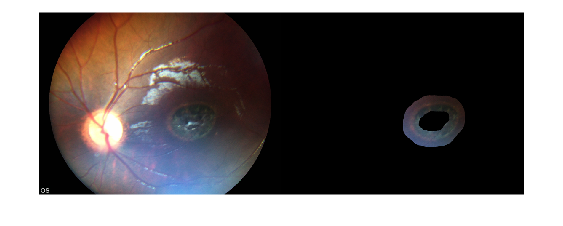

for i = 1:numImages
    % Get the image and mask filenames for the current iteration
    imageFilename = fullfile('Images', imageFiles(i).name);
    maskFilename = fullfile('Masks', maskFiles(i).name);

    % Create a folder with the same name as the image (e.g., '103')
    [~, imageName, ~] = fileparts(imageFiles(i).name);
    outputFolder = fullfile('output', imageName);
    if ~isfolder(outputFolder)
        mkdir(outputFolder);
    end

    % Load the image and its corresponding mask
    image = imread(imageFilename);
    mask = im2gray(imread(maskFilename));

    mask_diff = border(mask,n);
    imshow(mask_diff)

    % Modify the image based on the mask_diff
    new_img = image;
    new_img(repmat(~mask_diff, 1, 1, 3)) = 0;

    % montage
    montage_img = montage({image,new_img});

    % Extract pixel data from the montage image
    montage_data = montage_img.CData;

    % Save the original image in the current image's folder
    imwrite(image, fullfile(outputFolder, ['orig_', imageName, '.jpg']));

    % Save the ground truth in the current image's folder
    imwrite(mask, fullfile(outputFolder, ['gt_', imageName, '.jpg']));

    % Save the mask_diff in the current image's folder
    imwrite(mask_diff, fullfile(outputFolder, ['onion_mask_', imageName, '.jpg']));

    % Save the new_img in the current image's folder
    imwrite(new_img, fullfile(outputFolder, ['onion_img_', imageName, '.jpg']));

    % Save the montage data as an image in the current image's folder
    imwrite(montage_data, fullfile(outputFolder, ['mont_', imageName, '.jpg']));

end